## Sketch

Cell                                                                Gimbal

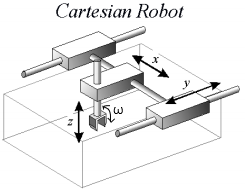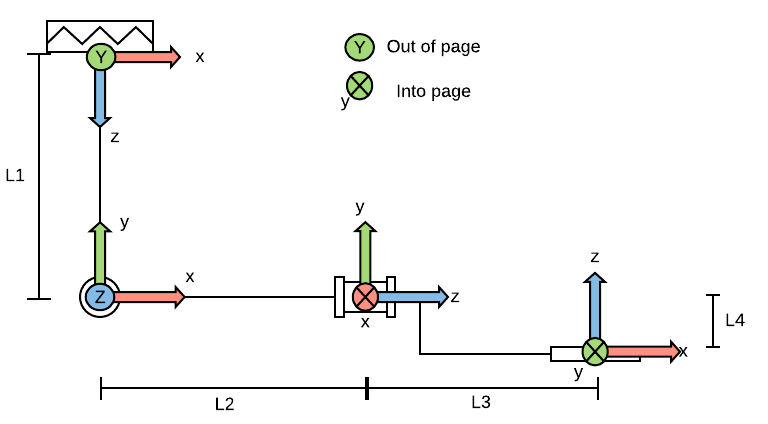    

## Lengths/Dimensions

clear all;
L1 = 0.0;
L2 = 0.2;
L3 = 0.2;
L4 = 0.0;

## Link Definitions

Gimbal

% L = Link ([Th d a alpha])
L_g(1)= Link([0 0.2 0 -pi/2,1],'standard');
L_g(1).qlim = ([0, 0]);
L_g(2)= Link([0 L2 0 0],'standard');
L_g(2).qlim = ([-pi/2, pi/2]);



PMJ Cell

% L = Link ([Th d a alpha])
L_c1 = 1;
L_c2 = 0.5;
L_c3 = 0.1;

% L_cell(1)= Link([0, 0, L_c1, pi/2, 1],'standard');
% L_cell(1).qlim = ([0, L_c1]);
% L_cell(2)= Link([0, 0, L_c2, pi/2, 1],'standard');
% L_cell(2).qlim = ([0, L_c2]);
% L_cell(3)= Link([0, L_c3, 0, 0,1, 1],'standard');
% L_cell(3).qlim = ([0, L_c3]);
% L_cell(4) = Link([0, 0, 0, 0],'standard');
% L_cell(4).qlim = ([-pi/2, pi/2]);

L_cell(1)= Link([-pi/2, 0, 0.1, pi/2, 1],'standard');
L_cell(1).qlim = ([0,1 ]);
L_cell(2)= Link([0, 0, 0.1, pi/2, 1],'standard');
L_cell(2).qlim = ([0, 1]);
L_cell(3)= Link([pi/2, -0, 0.1, 0, 1],'standard');
L_cell(3).qlim = ([0, 1]);


## Serial Kinematic Link

% plotOpt = ['name','pmj','workspace', [-1 1 -1 1 -1 1]]

pmj=SerialLink(L_g,'name','pmj_gimbal')

 
pmj = 
 
pmj_gimbal:: 2 axis, PR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|    -1.5708|          0|
|  2|         q2|        0.2|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


figure(1)
pmj.teach([0,0])
pmj_cell=SerialLink(L_cell,'name','pmj_cell')

 
pmj_cell = 
 
pmj_cell:: 3 axis, PPP, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|    -1.5708|         q1|        0.1|     1.5708|          0|
|  2|          0|         q2|        0.1|     1.5708|          0|
|  3|     1.5708|         q3|        0.1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% pmj_cell.teach([0,0,0])
% pmj_std = SerialLink()
% pmj_concat = pmj_cell * pmj 
% pmj = SerialLink(L,'plotopt',plotOpt);

## Tool Frame

toolHT=transl(0,0.2,0);

pmj.tool=toolHT;


## Base Frame

baseHT = transl(0,0,0)*trotz(pi/2);
pmj.base = baseHT

 
pmj = 
 
pmj_gimbal:: 2 axis, PR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|    -1.5708|          0|
|  2|         q2|        0.2|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0, 0, 0), RPY/xyz = (90, 0, 0) deg                 
tool:    t = (0, 0.2, 0), RPY/xyz = (0, 0, 0) deg                
 



pmj_cell.base = baseHT

 
pmj_cell = 
 
pmj_cell:: 3 axis, PPP, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|    -1.5708|         q1|        0.1|     1.5708|          0|
|  2|          0|         q2|        0.1|     1.5708|          0|
|  3|     1.5708|         q3|        0.1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0, 0, 0), RPY/xyz = (90, 0, 0) deg                 
 


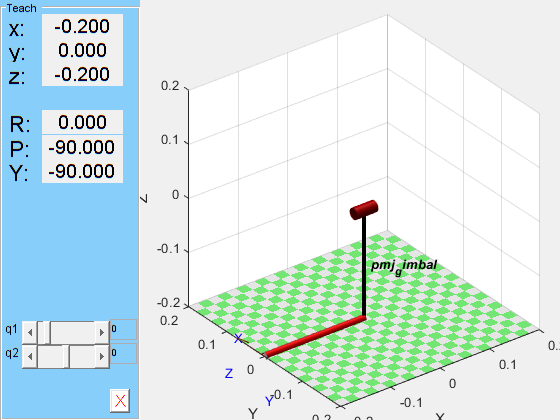

pmj.teach([0,0])

## Kinematic Chain

s = pmj.trchain('sym')

s = 'Tz(q1)Rx(-90)Rz(q2)Tz(L1)'

## Plot Manipulator)

% figure(2)
% q1 = pi/2; q2 = 1;
% subplot(1,2,1)
% pmj.plot([q1,q2])
% subplot(1,2,2)
% pmj_cell.plot([1,0.5,0])

## Forward Kinematics

% toolPos = pmj.fkine([q1, q2]);
% disp(toolPos)

## Inverse Kinematics

Target Pose

% figure(3)
% hold on
% poseHT = transl(0.4,0,0)*trotx(pi/2);
% trplot(poseHT, 'frame', 'Trgt', 'color', 'm','length', 0.3)

Inverse kinematics with ikcon (with joint limits)

%initial guess
% q0=[0, 0];
% q2 = pmj.ikinem(poseHT)
% q1= pmj.ikine(poseHT,q0,'qlimits','mask',[1,0,1,1,0,0])
% [q,err] = pmj.ikcon(poseHT,q0);
% q_deg = q * 180/pi;

Calculated Joint angles

% display(q_deg)
% display(err)

Plotting Result

% pmj.plot(q,'wrist','jaxes','nobase', 'noshadow', 'noshading',...
%         'floorlevel',0.4,'raise','zoom',0.5,... 
%         'workspace', [-0.2 0.8 -0.2 0.2 -0.5 0.5])